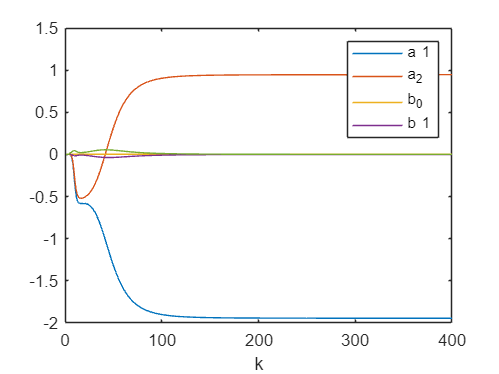

% Recursive least squares parameter estimation (RLS)

clear all; close all;
d=1; 	        % Plant parameters
na=2; nb=2; 	% na and nb are the order of A and B
Ts=0.01;                                                                                                                
L=400;                              % Simulation length
uk=zeros(d+nb,1);                   % Initial values of the input: uk(i) means u(k-i)
yk=zeros(na,1);                     % Initial values of the output: 
thetaE_1=zeros(na+nb+1,1);          % Initial values of thetae
P=10^6*eye(na+nb+1);

for k=1:L 
    Phi=[-yk;uk(d:d+nb)]; 			% Phi is the column vector
    
    % Input-Output data
    u(k)=Ts*k;
    % 可以写出传递函数。如果懒得写，可以逐个尝试an nb的值  nb很好确定，逐个增大，到后面theta出现0的前一阶
    % na不易确定，一般到出现矩阵奇异的前一阶
    y(k)=Ts*k-0.2+1/(5*sqrt(0.75))*exp(-2.5*Ts*k)*sin(5*sqrt(0.75)*Ts*k+2*atan(sqrt(3)));
    
    % Recursive least squares method
    K=P*Phi/(1+Phi'*P*Phi);
    thetaE(:,k)=thetaE_1+K*(y(k)-Phi'* thetaE_1);
    P=(eye(na+nb+1)-K*Phi')*P;		% Update data
    thetaE_1=thetaE(:,k);
    for i=d+nb:-1:2  uk(i)=uk(i-1);  end
    uk(1)=u(k);
    for i=na:-1:2  yk(i)=yk(i-1);  end
    yk(1)=y(k);
end

plot([1:L],thetaE); 				% line([1,L],[theta,theta]);
xlabel('k'); 
legend('a_ 1','a_2','b_0','b_ 1'); 
axis([0 L -2 1.5]);


thetaE(:,L)

ans =    -1.9442
    0.9469
    0.0024
   -0.0004
    0.0007


Den=[1 thetaE(1:2,L)'];
Num=[thetaE(3:4,L)'];
sysd=tf(Num,Den,Ts);
sysc=d2c(sysd,'zoh')

sysc =
 
    0.1438 s + 20.62
  ---------------------
  s^2 + 5.459 s + 27.34
 
连续时间传递函数。
模型属性



% sysc=tf(25,[1 5 25]);
% c2d(sysc,Ts)


